clear; clc; close all;

flyby_id = 'E4';   % options: E4, E14, E19, E26, custom_file

## main loops

% define constants
r_m = 1560; % Europa radius (km)
A = 0.95; % amplitude response factor
phi = 0.14; % phase lag in radians
synodic_period = 11.23 * 3600; % 11.23 hr period
omega = 2*pi / (synodic_period); % synodic freq. (rad/sec)

% elliptical primary field amplitudes from Zimmer's range (IS-system)
Bprim_x_amp = 67;  % azimuthal (orbital travel direction)
Bprim_y_amp = 225; % radial (pointing toward Jupiter)
Bprim_z_amp = -410;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% flyby-specific parameters 
% each case must define:
%   traj_t    : nx1, seconds elapsed since the start of the encounter

%   traj_pos  : nx3, [x y z] spacecraft position in km, in the same
%               coordinate system as the model (x = azimuthal,
%               y = radial toward Jupiter, z = spin axis)

%   phi0      : phase offset (rad) that aligns the model's oscillation
%               with the real Jovian field phase at traj_t = 0.
%               until the true value is calculated, phi0 = 0 just
%               means "unsynchronized"  the shape of B(t) along the
%               trajectory is still meaningful, but its timing relative
%               to real events (e.g. plasma sheet crossings) is not.


switch flyby_id

  case 'E4'
        data_file = fullfile('flyby data', 'ORB04_EUR_EPHIO.TAB');
        [traj_t, traj_pos B_meas] = load_galileo_tab(data_file);
        phi0 = 0.0;                 
        grid_limit = r_m * 7;
 
    case 'E14'
        data_file = fullfile('flyby data', 'ORB14_EUR_EPHIO.TAB');
        [traj_t, traj_pos B_meas] = load_galileo_tab(data_file);
        phi0 = 0.0;                 
        grid_limit = r_m * 8.5;
        
 
    case 'E19'
        data_file = fullfile('flyby data', 'ORB19_EUR_EPHIO.TAB');
        [traj_t, traj_pos B_meas] = load_galileo_tab(data_file);
        phi0 = 0.0;                 
        grid_limit = r_m * 6.6;
 
    case 'E26'
        data_file = fullfile('flyby data', 'ORB26_EUR_EPHIO.TAB');
        [traj_t, traj_pos B_meas] = load_galileo_tab(data_file);
        phi0 = 0.0;                 
        grid_limit = r_m * 13;
 
    case 'custom_file'
        % for any other ephio .tab file with the same column layout as
        % the E4/E14/E16/E26 cases 
        data_file = fullfile('flyby data', 'galileo_trajectory.tab');   
        [traj_t, traj_pos] = load_galileo_tab(data_file);
        phi0 = 0.0;                     
        grid_limit = r_m * 7;            

    otherwise
        error('Unknown flyby_id: %s', flyby_id);
end

% estimate phi0 from far-field points

R_traj = sqrt(sum(traj_pos.^2, 2));
far_thresh = 3 * r_m; % "far field" = negligible secondary field
far_idx = find(R_traj > far_thresh & ~any(isnan(B_meas(:,1:2)), 2));

theta_meas = atan2(B_meas(far_idx,2)/Bprim_y_amp, B_meas(far_idx,1)/Bprim_x_amp);
phi0_est = mod(theta_meas - omega*traj_t(far_idx) + pi, 2*pi) - pi; % wrap to [-pi,pi]

circ_mean = @(x) atan2(mean(sin(x)), mean(cos(x)));

phi0_start = circ_mean(phi0_est(traj_t(far_idx) < traj_t(end)/2));
phi0_end = circ_mean(phi0_est(traj_t(far_idx) >= traj_t(end)/2));

fprintf('phi0 estimate (start of pass): %.4f rad\n', phi0_start);

phi0 estimate (start of pass): -0.6210 rad


fprintf('phi0 estimate (end of pass): %.4f rad\n', phi0_end);

phi0 estimate (end of pass): -1.2738 rad


fprintf('phi0 estimate (all far pts): %.4f rad\n', circ_mean(phi0_est));

phi0 estimate (all far pts): -1.1147 rad



fprintf('N points (start half): %d\n', sum(traj_t(far_idx) < traj_t(end)/2));

N points (start half): 1089


fprintf('N points (end half): %d\n', sum(traj_t(far_idx) >= traj_t(end)/2));

N points (end half): 3267





R_start = R_traj(far_idx(traj_t(far_idx) < traj_t(end)/2));
R_end = R_traj(far_idx(traj_t(far_idx) >= traj_t(end)/2));

fprintf('R (start half): mean=%.1f km (%.2f r_m), min=%.1f, max=%.1f\n', ...
 mean(R_start), mean(R_start)/r_m, min(R_start), max(R_start));

R (start half): mean=5613.4 km (3.60 r_m), min=4689.0, max=6873.8


fprintf('R (end half): mean=%.1f km (%.2f r_m), min=%.1f, max=%.1f\n', ...
 mean(R_end), mean(R_end)/r_m, min(R_end), max(R_end));

R (end half): mean=7475.7 km (4.79 r_m), min=4683.8, max=10633.9



% weight far-field phi0 estimates by distance (further = more trustworthy)
weights = R_traj(far_idx) - far_thresh; % more weight to points further beyond cutoff
sin_avg = sum(weights .* sin(phi0_est)) / sum(weights);
cos_avg = sum(weights .* cos(phi0_est)) / sum(weights);
phi0 = atan2(sin_avg, cos_avg);
fprintf('phi0 estimate (distance-weighted): %.4f rad\n', phi0);

phi0 estimate (distance-weighted): -1.2544 rad


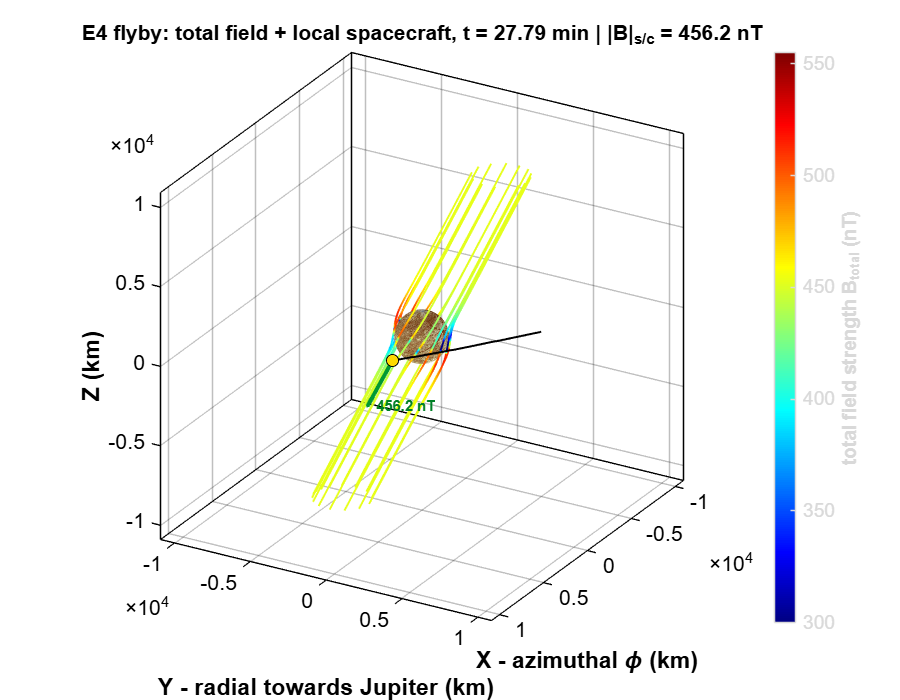


[~, i_min] = min(R_traj);
t_CA = traj_t(i_min) / 60; % in minutes

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% create spatial grid (used for streamline background field, same as before)

num_points = 70;
[X, Y, Z] = meshgrid(linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points), ...
                     linspace(-grid_limit, grid_limit, num_points));

R = sqrt(X.^2 + Y.^2 + Z.^2);
mask = R >= r_m;

% down-sample the trajectory to a manageable number of animation frames
num_frames = min(120, length(traj_t));
frame_idx = round(linspace(1, length(traj_t), num_frames));


% storage for the actual sampled B values along the trajectory 
t_series = traj_t(frame_idx);
Bmeas_series = B_meas(frame_idx, :); 
Bx_series = zeros(size(frame_idx));
By_series = zeros(size(frame_idx));
Bz_series = zeros(size(frame_idx));
Bmag_series = zeros(size(frame_idx));

fig = figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 700]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% load and prep image texture
planetImage = imread('europaimage.jpg');
shiftAmount = round(size(planetImage,2) * 1); % adjust to hide seam for current view
shiftedImage = circshift(planetImage, shiftAmount, 2);
[sx, sy, sz] = sphere(200);


% animation loop, one frame per sampled trajectory point
for fi = 1:length(frame_idx)

    k = frame_idx(fi);
    t = traj_t(k);              % seconds since encounter start
    sc_pos = traj_pos(k, :);    % current spacecraft position [x y z] (km)

    r_dot_e0x = X;
    r_dot_e0y = Y;

    % complex secondary field: x-driven
    coefx_c = -(A * Bprim_x_amp * r_m^3) .* exp(-1i*(omega * t + phi0 - phi)) ./ (2 * R.^5);
    Bsecx_x = coefx_c .* (3 * r_dot_e0x .* X - R.^2);
    Bsecx_y = coefx_c .* (3 * r_dot_e0x .* Y);
    Bsecx_z = coefx_c .* (3 * r_dot_e0x .* Z);

    % complex secondary field: y-driven (90 deg / pi/2 shifted)
    coefy_c = -(A * Bprim_y_amp * r_m^3) .* exp(-1i*(omega*t + phi0 - pi/2 - phi)) ./ (2 * R.^5);
    Bsecy_x = coefy_c .* (3 * r_dot_e0y .* X);
    Bsecy_y = coefy_c .* (3 * r_dot_e0y .* Y - R.^2);
    Bsecy_z = coefy_c .* (3 * r_dot_e0y .* Z);

    % complex primary background field (phi0 shifts this to the real
    % Jovian phase at the start of the encounter)
    Bprim_c_x = Bprim_x_amp * exp(-1i*(omega*t + phi0));
    Bprim_c_y = Bprim_y_amp * exp(-1i*(omega*t + phi0 - pi/2));
    Bprim_c_z = Bprim_z_amp;

    % superimpose total fields and take real components
    Bx = real(Bsecx_x + Bsecy_x + Bprim_c_x);
    By = real(Bsecx_y + Bsecy_y + Bprim_c_y);
    Bz = real(Bsecx_z + Bsecy_z + Bprim_c_z);

    % zero interior field matrix
    Bx(~mask) = 0;
    By(~mask) = 0;
    Bz(~mask) = 0;

    % total field magnitude
    B_mag = sqrt(Bx.^2 + By.^2 + Bz.^2);

    % sample the field at the spacecraft's position analytically (same formula
    % as the grid, but evaluated as a single point) works everywhere
    % along the real trajectory, even where it leaves the visualization grid
    xs = sc_pos(1); ys = sc_pos(2); zs = sc_pos(3);
    Rs = sqrt(xs^2 + ys^2 + zs^2);

    if Rs < r_m
        % inside Europa 
        Bx_sc = 0; By_sc = 0; Bz_sc = 0;
    else
        coefx_c_s = -(A * Bprim_x_amp * r_m^3) * exp(-1i*(omega*t + phi0 - phi)) / (2 * Rs^5);
        Bsecx_x_s = coefx_c_s * (3 * xs * xs - Rs^2);
        Bsecx_y_s = coefx_c_s * (3 * xs * ys);
        Bsecx_z_s = coefx_c_s * (3 * xs * zs);

        coefy_c_s = -(A * Bprim_y_amp * r_m^3) * exp(-1i*(omega*t + phi0 - pi/2 - phi)) / (2 * Rs^5);
        Bsecy_x_s = coefy_c_s * (3 * ys * xs);
        Bsecy_y_s = coefy_c_s * (3 * ys * ys - Rs^2);
        Bsecy_z_s = coefy_c_s * (3 * ys * zs);

        Bprim_c_x_s = Bprim_x_amp * exp(-1i*(omega*t + phi0));
        Bprim_c_y_s = Bprim_y_amp * exp(-1i*(omega*t + phi0 - pi/2));
        Bprim_c_z_s = Bprim_z_amp;

        Bx_sc = real(Bsecx_x_s + Bsecy_x_s + Bprim_c_x_s);
        By_sc = real(Bsecx_y_s + Bsecy_y_s + Bprim_c_y_s);
        Bz_sc = real(Bsecx_z_s + Bsecy_z_s + Bprim_c_z_s);
    end

    % log the actual numeric values 
    Bx_series(fi) = Bx_sc;
    By_series(fi) = By_sc;
    Bz_series(fi) = Bz_sc;
    Bmag_series(fi) = norm([Bx_sc, By_sc, Bz_sc]);

    % dynamic equator tracking from total primary field direction
    Bx_prim_now = real(Bprim_c_x);
    By_prim_now = real(Bprim_c_y);
    Bz_prim_now = real(Bprim_c_z);


    % seeds
    m_real = [Bx_prim_now; By_prim_now; Bz_prim_now];
    m_hat = m_real / norm(m_real);

    v1 = cross(m_hat, [0; 0; 1]);
    if norm(v1) < 1e-6
        v1 = cross(m_hat, [1; 0; 0]);
    end
    v1 = v1 / norm(v1);
    v2 = cross(m_hat, v1);
    v2 = v2 / norm(v2);

    num_seeds_per_ring = 16;
    theta = linspace(0, 2*pi, num_seeds_per_ring);
    radii_layers = 1.1 * r_m;

    total_seeds = length(radii_layers) * num_seeds_per_ring;
    seed_X = zeros(1, total_seeds);
    seed_Y = zeros(1, total_seeds);
    seed_Z = zeros(1, total_seeds);

    idx = 1;
    for r_seed = radii_layers
        for kk = 1:length(theta)
            pt = r_seed * (cos(theta(kk))*v1 + sin(theta(kk))*v2);
            seed_X(idx) = pt(1);
            seed_Y(idx) = pt(2);
            seed_Z(idx) = pt(3);
            idx = idx + 1;
        end
    end

    clf;
    set(gcf, 'Color', 'w');

    % draw solid Europa sphere

    h = surf(sx * r_m, sy * r_m, sz * r_m, ...
        'FaceColor', 'texturemap', ...
        'CData', flipud(shiftedImage), ...
        'EdgeColor', 'none', ...
        'FaceLighting', 'gouraud');
    hold on;
    axis equal;

    set(h, 'FaceLighting', 'gouraud', 'AmbientStrength', 0.4, 'SpecularStrength', 0.1);

    verts_forward = stream3(X, Y, Z, Bx, By, Bz, seed_X(:), seed_Y(:), seed_Z(:));
    verts_backward = stream3(X, Y, Z, -Bx, -By, -Bz, seed_X(:), seed_Y(:), seed_Z(:));

    for kk = 1:num_seeds_per_ring
        v_f = verts_forward{kk};
        v_b = verts_backward{kk};

        if isempty(v_f) && isempty(v_b)
            continue;
        elseif isempty(v_f)
            v = v_b;
        elseif isempty(v_b)
            v = v_f;
        else
            v = [flipud(v_b); v_f];
        end

        line_colors = interp3(X, Y, Z, B_mag, v(:,1), v(:,2), v(:,3));

        surf_x = [v(:,1)'; v(:,1)'];
        surf_y = [v(:,2)'; v(:,2)'];
        surf_z = [v(:,3)'; v(:,3)'];
        surf_c = [line_colors'; line_colors'];

        surface(surf_x, surf_y, surf_z, surf_c, ...
                'FaceColor', 'none', ...
                'EdgeColor', 'interp', ...
                'LineWidth', 1.4);
    end

    % spacecraft marker, trailing path, local B vector arrow
    plot3(traj_pos(1:k,1), traj_pos(1:k,2), traj_pos(1:k,3), ...
          'k-', 'LineWidth', 1.5);
    plot3(sc_pos(1), sc_pos(2), sc_pos(3), 'o', ...
          'MarkerFaceColor', [1 0.85 0], 'MarkerEdgeColor', 'k', 'MarkerSize', 9);

    Bsc_norm = norm([Bx_sc, By_sc, Bz_sc]);
    if Bsc_norm > 1e-3
        arrow_scale = (2.2 * r_m) / Bsc_norm;
        quiver3(sc_pos(1), sc_pos(2), sc_pos(3), ...
                Bx_sc*arrow_scale, By_sc*arrow_scale, Bz_sc*arrow_scale, ...
                'Color', [0 0.6 0.2], 'LineWidth', 3, 'MaxHeadSize', 0.6, 'AutoScale', 'off');
        tip = sc_pos + [Bx_sc, By_sc, Bz_sc] * arrow_scale;
        text(tip(1), tip(2), tip(3), sprintf('  %.1f nT', Bsc_norm), ...
            'Color', [0 0.5 0.15], 'FontWeight', 'bold', 'FontSize', 11);
    end

    colormap(jet);
    c = colorbar;
    ylabel(c, 'total field strength B_{total} (nT)', 'FontWeight', 'bold');

    clim([300, 555]);

    axis equal; grid on; box on;
    xlim([-grid_limit, grid_limit]);
    ylim([-grid_limit, grid_limit]);
    zlim([-grid_limit, grid_limit]);

    ax = gca;
    set(ax, 'XColor', 'k', 'YColor', 'k', 'FontSize', 16, 'ZColor', 'k', 'Color', 'w');
    xlabel('X - azimuthal \phi (km)', 'FontWeight', 'bold');
    ylabel('Y - radial towards Jupiter (km)', 'FontWeight', 'bold');
    zlabel('Z (km)', 'FontWeight', 'bold');

    view([120 25]);

    title(sprintf('%s flyby: total field + local spacecraft, t = %.2f min | |B|_{s/c} = %.1f nT', ...
        strrep(flyby_id, '_', '\_'), t/60, Bsc_norm), ...
        'Color', 'k', 'FontSize', 16, 'FontWeight', 'bold');

    drawnow;
    pause(0.04);
end

## stackplots

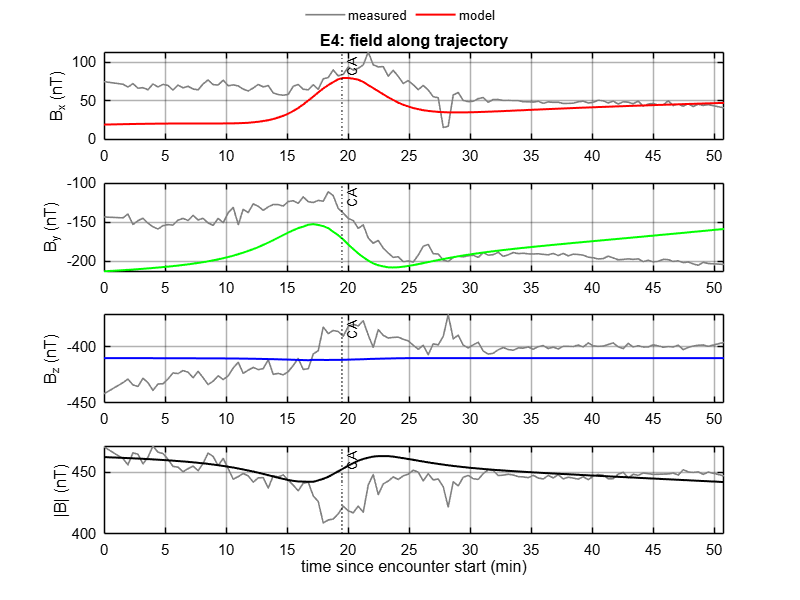

figure('Color', 'w', 'Position', [150, 150, 800, 600]);
 
subplot(4,1,1);
h1 = plot(t_series/60, Bmeas_series(:,1), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
h2 = plot(t_series/60, Bx_series, 'r-', 'LineWidth', 1.5);
ylabel('B_x (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
title(sprintf('%s: field along trajectory', flyby_id), 'Interpreter', 'none', 'Color', 'k');
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,2);
plot(t_series/60, Bmeas_series(:,2), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, By_series, 'g-', 'LineWidth', 1.5);
ylabel('B_y (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,3);
plot(t_series/60, Bmeas_series(:,3), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, Bz_series, 'b-', 'LineWidth', 1.5);
ylabel('B_z (nT)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);
 
subplot(4,1,4);
plot(t_series/60, Bmeas_series(:,4), 'Color', [0.5 0.5 0.5], 'LineWidth', 1.2); hold on;
plot(t_series/60, Bmag_series, 'k-', 'LineWidth', 1.5);
ylabel('|B| (nT)', 'Color', 'k'); xlabel('time since encounter start (min)', 'Color', 'k'); grid on;
xline(t_CA, 'k:', 'CA', 'LineWidth', 1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', 'k', 'GridAlpha', 0.3, 'FontSize', 11);

lgd = legend([h1 h2], {'measured', 'model'}, 'Orientation', 'horizontal', 'TextColor', 'k');
lgd.Position = [0.4, 0.96, 0.2, 0.03];   
lgd.Box = 'off';

xlims = [0, max(traj_t)/60];   % full measured time range, in minutes

subplot(4,1,1); xlim(xlims);
subplot(4,1,2); xlim(xlims);
subplot(4,1,3); xlim(xlims);
subplot(4,1,4); xlim(xlims);

 
% print raw numbers
fprintf('\n%-10s %-10s %-10s %-10s %-10s\n', 't (min)', 'Bx', 'By', 'Bz', '|B|');


t (min)    Bx         By         Bz         |B|       


for fi = 1:5:length(t_series)
    fprintf('%-10.2f %-10.2f %-10.2f %-10.2f %-10.2f\n', ...
        t_series(fi)/60, Bx_series(fi), By_series(fi), Bz_series(fi), Bmag_series(fi));
end

0.00       19.07      -212.61    -410.03    462.27    
3.19       20.06      -209.37    -410.07    460.86    
5.24       20.43      -206.58    -410.11    459.66    
7.30       20.52      -202.81    -410.18    458.04    
9.35       20.53      -197.30    -410.25    455.69    
11.41      21.10      -188.65    -410.47    452.24    
13.46      24.79      -175.84    -410.86    447.59    
15.51      36.75      -160.05    -411.49    443.05    
17.55      60.75      -153.26    -411.60    443.39    
19.60      79.48      -171.82    -411.52    452.98    
21.65      70.10      -198.91    -410.82    461.79    
23.69      50.98      -207.65    -410.27    462.64    
25.74      39.05      -203.40    -410.02    459.36    
27.79      35.19      -196.89    -409.98    456.16    
29.84      34.98      -191.33    -409.97    453.77    
31.89      36.05      -186.91    -409.99    452.03    
33.93      37.44      -183.25    -409.99    450.64    
35.98      38.88      -179.98    -409.99    449.44    
38.03     

## functions


% local functions

function [traj_t, traj_pos, B_meas] = load_galileo_tab(filename)
% loads a PDS Galileo mag+trajectory .tab file in ephio coordinates
% from lbl file, columns are:
%   1   : spacecraft event time, ISO 8601
%   2-4 : BX, BY, BZ measured magnetic field (nT)  -- missing = 999999.99
%   5   : |B| magnitude (nT)                        -- missing = 999999.99
%   6-8 : X, Y, Z spacecraft position in EUROPA RADII (RE = 1560 km)
%         -- missing = 999.99

% returns:
%   traj_t   : Nx1, seconds elapsed since the first row in the file
%   traj_pos : Nx3, [x y z] position in km (converted from Europa radii)
%   B_meas   : Nx4, [Bx By Bz Bmag] measured field in nT 

RE = 1560; % Europa radius on lbl

raw = readlines(filename);
raw = raw(strlength(strtrim(raw)) > 0);
n = length(raw);

t_dt = NaT(n,1);
B_meas = zeros(n,4);
traj_pos = zeros(n,3);

for i = 1:n
    parts = strsplit(strtrim(raw(i)));
    t_dt(i) = datetime(parts{1}, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss.SSS');
    B_meas(i,:) = str2double(parts(2:5));           % Bx, By, Bz, |B| 
    traj_pos(i,:) = str2double(parts(6:8)) * RE;     
end

% missing-value handling
B_meas(B_meas > 999998) = NaN;
traj_pos(abs(traj_pos) > 999.98*RE) = NaN;

traj_t = seconds(t_dt - t_dt(1));
end


% this function is for inputting my own values
% to use it make a
% case in the switch block back to calling this function with my own
% CA_alt / v_sc / approach_dir values instead of load_galileo_tab()

function [traj_t, traj_pos] = make_synthetic_flyby(r_m, CA_alt, v_sc, approach_dir)
% builds a straight-line flyby trajectory as a placeholder, passing
% Europa at closest approach altitude CA_alt (km) with speed v_sc (km/s)
% along direction approach_dir

    b = r_m + CA_alt;                     % impact parameter (km)
    dir_travel = approach_dir / norm(approach_dir);

    perp = cross(dir_travel, [0 0 1]);
    if norm(perp) < 1e-6
        perp = cross(dir_travel, [1 0 0]);
    end
    perp = perp / norm(perp);
    ca_point = b * perp;                  % closest-approach point

    half_range = 3 * r_m;                 % extent of trajectory shown (km)
    n_pts = 200;
    s = linspace(-half_range, half_range, n_pts)';   % along-track distance

    traj_pos = ca_point + s * dir_travel;             % Nx3, km
    traj_t = s / v_sc;                                 % seconds
    traj_t = traj_t - traj_t(1);                       % re-zero to start at 0
end